# Latency analysis

clc; clear; close all;

## Dataset name

Enter below the dataset name. The file should contain a single json array.

fname_pub = 'public_sign.json';
fname_priv = 'private_sign.json';

## Load data

Load the data into memory.

json_pub = load_data(fname_pub);
json_priv = load_data(fname_priv);

## Extract data

Save all the timings for machine.

[ids, mu_pub, std_pub] = analyse(json_pub);
[~, mu_priv, std_priv] = analyse(json_priv);

## Plot

Plot mean and standard deviation.

% plot mean and standard deviation
x = 1:length(ids);
mu_pub

mu_pub =    17.0756   17.7890   18.2850   18.7511   19.1840   19.6067   20.0487   20.4849   20.9343   21.3591


mu_priv

mu_priv =    19.1648   19.7482   20.2404   20.6625   21.1003   21.5937   22.0619   22.5782   23.0350   23.4678


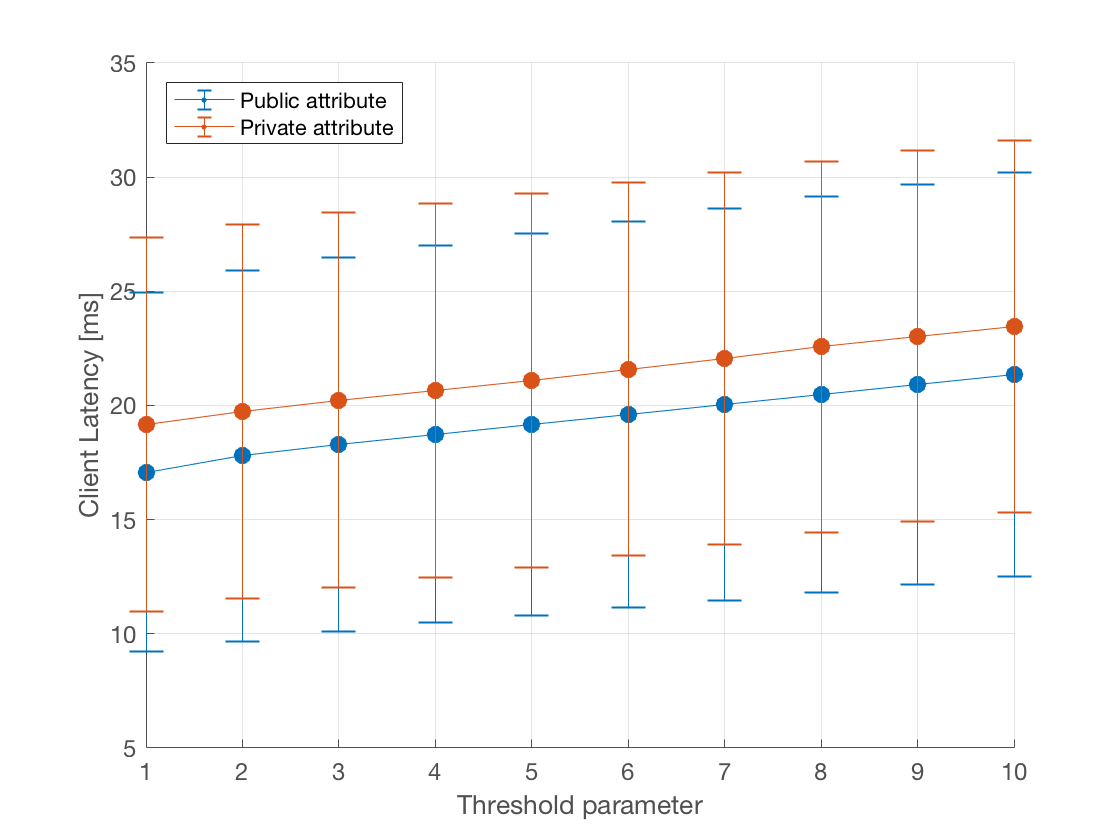

createfigure([x' x'],[mu_pub' mu_priv'],[std_pub' std_priv']);